# Exercise 2: Investigation of Whirling Modes with Nacelle Rotor Assembly

Prof. Dr.-Ing. Jens Geisler, last update 3 July 2025

## Preamble

Let's start with a clean workspace and set up the required path. Make sure you are in the examples folder of the CADynM Project!

**This exercise it divided into several sections. Use ****Strg+Enter**** / Ctrl+Enter to run individial sections and avoid unnecessary computation of the others.**

addpath('../toolbox')
clear

## Modeling

We start again by creating a multibody system object.

turbine= MultiBodySystem('Turbine');

The DOF shall be:

%  nacelle yaw angle
turbine.addGeneralizedCoordinate('phi_az')
% rotor rotation angle
turbine.addGeneralizedCoordinate('phi_rot')
% one flap-wise modal deformation for each blade
turbine.addGeneralizedCoordinate('e_b1')
turbine.addGeneralizedCoordinate('e_b2')
turbine.addGeneralizedCoordinate('e_b3')

The inputs shall be:

% rotor (hub) torque
turbine.addInput('Trot')
% one modal force for each blade
turbine.addInput('Fb1')
turbine.addInput('Fb2')
turbine.addInput('Fb3')

Various geometric and mass parameters and setting the gravity in negative Z-direction (coordinates like in OpenFAST):

turbine.addParameter('NacMass');
turbine.addParameter('NacXIner');
turbine.addParameter('NacYIner');
turbine.addParameter('NacZIner');
turbine.addParameter('NacCMxn');
turbine.addParameter('NacCMyn');
turbine.addParameter('NacCMzn');
turbine.addParameter('HubMass');
turbine.addParameter('HubIner');
turbine.addParameter('HubCM');
turbine.addParameter('OverHang');
turbine.addParameter('Twr2Shft');
turbine.addParameter('YawSpr');
turbine.addParameter('YawDamp');
turbine.addParameter('g');
turbine.gravity(3) = -turbine.params.g; % negative Z

Now we create the nacelle, set its mass parameters and its dynamic pose and add it to the system (inertial reference). The nacelle can rotate about the z-axis (yaw) and has a center of mass that is not aligned with the yaw axis.

nacelle= RigidBody('nacelle');
nacelle.m= turbine.params.NacMass;
nacelle.I(1,1)= turbine.params.NacXIner;
nacelle.I(2,2)= turbine.params.NacYIner;
nacelle.I(3,3)= turbine.params.NacZIner;

nacelle.rotateLocalAxis('z', turbine.dof.phi_az);
nacelle.translate([turbine.params.NacCMxn turbine.params.NacCMyn turbine.params.NacCMzn]);

turbine.addChild(nacelle)

Then we add the hub, set its mass parameters and its dynamic pose relative to the nacelle and add it to the nacelle! The center of mass of the hub is in front of the turbine (OverHang) and it can rotate about the x-axis (no tilt is considerd for now).

hub= RigidBody('hub');
hub.m= turbine.params.HubMass;
hub.I(1,1)= turbine.params.HubIner; % assume interia is equal about all axis
hub.I(2,2)= turbine.params.HubIner; % only the x intertia is really relevant
hub.I(3,3)= turbine.params.HubIner;

hub.translate([turbine.params.HubCM+turbine.params.OverHang-turbine.params.NacCMxn, -turbine.params.NacCMyn, turbine.params.Twr2Shft-turbine.params.NacCMzn]);
hub.rotateLocalAxis('x', turbine.dof.phi_rot);

nacelle.addChild(hub)

Finally we add the three blades and add them to the hub. Each blade is offset by 120° about the x-axis. No cone and pitch angles are considered for now.

load('blade_sid')
for i = 1:3
    bl_dof = sprintf('e_b%d', i);
    blade(i)= ElasticBody(turbine.dof.(bl_dof), bd_sid, sprintf('blade%d', i));
    
    blade(i).translate([-turbine.params.HubCM, 0, 0]);
    blade(i).rotateLocalAxis('x', (i-1)*2*pi/3);
    
    hub.addChild(blade(i))
end

Apart from the external forces we also add a spring and damper force that keeps the nacelle at zero degree yaw using stiffness and damping parameters and the respective positional DOF and its derivative (velocity). 

% tower torsion spring stiffness and damping
nacelle.applyMoment([0; 0; -turbine.params.YawSpr*turbine.dof.phi_az])
nacelle.applyMoment([0; 0; -turbine.params.YawDamp*turbine.dof.phi_az_d])

% external input combined wind and generator torque
hub.applyMoment([turbine.inputs.Trot; 0; 0])

% external input blade modal forces
blade(1).applyElasticForce(turbine.inputs.Fb1)
blade(2).applyElasticForce(turbine.inputs.Fb2)
blade(3).applyElasticForce(turbine.inputs.Fb3)

## Create EOM

Again, we prepare the kinematics and generate the ode function.

turbine.completeSetup()
turbine.eomDae('Turbine_DAE.m')

**TASK01:** Open the generated ODE function and inspect its contents. The second order ode has been transformed into a first order ode. The equations are optimized. Common terms are precomputed and reused. You can no longer analyse and understand the equations!

## Simulation

Before the simulation can start, we need to set the parameter values in a struct with names according to the ones we declared in the system. Then we need to transform these parameters into a vector.

p.NacMass = 240000;
p.NacXIner = 0;
p.NacYIner = 0;
p.NacZIner = 2607890;
p.NacCMxn = 1.9;
p.NacCMyn = 0;
p.NacCMzn = 1.75;
p.HubMass = 56780;
p.HubIner = 115926;
p.HubCM = 0;
p.OverHang = -5.0191;
p.Twr2Shft = 1.9626;
p.YawSpr = 9.02832E+09/3.5^2;
p.YawDamp = 1.916E+07;
p.g = 0;

params= turbine.paramVec(p);

We will use one common function to define zero value input puts.

no_input= @(t)0;

Then we need to prepare the ode-function for the simulation as a lambda to set the input functions and parameters.

F = @(t,Y,YP) Turbine_DAE(t, Y, YP, [no_input(t),no_input(t),no_input(t),no_input(t)], [], params);


Now, let's configure the simulation run time, the initial states and the solver options and run the simulation. The simulations shall start with the blade 1 being deflected by one (meter at the tip) and a rotor speed equivalent to 1200 rpm generator speed. Notice, how the state indeces can be used to set specific values. To set velocity states, `turbine.n_dof` must be added to the DOF index, because the state vector of the first order ode contains both, the positions and the velocities. The derivative of the initial state, `dx0`, is only a guess that we set consistent with the state. 

t_end= 50;

x0 = [0 0 0 0 0 0 0 0 0 0]';
x0(turbine.dof_idx.phi_rot+turbine.getNumDOF) = 1200/30*pi/97;
x0(turbine.dof_idx.e_b1) = 1;

dx0= [x0(turbine.getNumDOF+1:end)' 0*x0(turbine.getNumDOF+1:end)']';

opt= odeset(AbsTol=1e-5, RelTol=1e-3);

sim_res= ode15i(F, [0,t_end], x0, dx0, opt);

To visualize the solution result, we plot the yaw angle of the nacelle, the rotation speed of the rotor and the three blade deflection states.

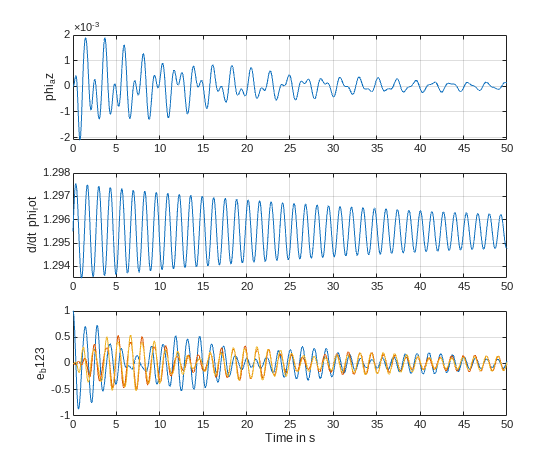

tiledlayout(3,1)
nexttile
plot(sim_res.x, sim_res.y(turbine.dof_idx.phi_az, :))
ylabel('phi_az')
grid on

nexttile
plot(sim_res.x, sim_res.y(turbine.dof_idx.phi_rot+turbine.getNumDOF, :))
ylabel('d/dt phi_rot')
grid on

nexttile
plot(sim_res.x, sim_res.y([turbine.dof_idx.e_b1 turbine.dof_idx.e_b2 turbine.dof_idx.e_b3], :))
ylabel('e_b123')
xlabel('Time in s')
grid on

**TASK02:** Set different initial rotor speeds and observe, how the results change.

**TASK03:** Set the initial blade deflection to zero and instead the initial nacelle azmuth to 1°. What happenes to the blades?

## Analysis

Now we want to investigate the whirling modes. For this, we

- Run in a loop several simulations with different rotor speeds.

- Compute the psd of the nacell yaw angle. We uses this as a "sensor" for the effect of the blade oscillation in the non-rotating frame.

- Extract the two most prominent peaks from the psd and collect them in a vector.

- Plot the two frequencies with respect to the rotor speed.

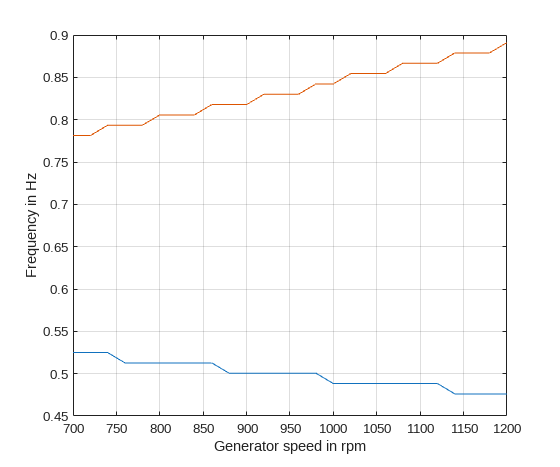

RPM= 700:20:1200;
t_end= 200;
dt= 0.02;

x0 = [0 0 0 0 0 0 0 0 0 0]';
x0(turbine.dof_idx.e_b1) = 1;

f1= zeros(length(RPM), 1);
f2= zeros(length(RPM), 1);

for i= 1:length(RPM)
    x0(turbine.dof_idx.phi_rot+turbine.getNumDOF)= RPM(i)/30*pi/97;
    dx0= [x0(turbine.getNumDOF+1:end)' 0*x0(turbine.getNumDOF+1:end)']';

    sim_res= ode15i(F, [0,t_end], x0, dx0, opt);

    phi_az_sim = interp1(sim_res.x, sim_res.y(turbine.dof_idx.phi_az, :), 0:dt:t_end);
    [pxx, f]=pwelch(phi_az_sim, [], [], [], 1/dt);

    [~, efs] = findpeaks(10*log10(pxx), f, 'NPeaks', 2, 'SortStr', 'descend');
    f1(i)= min(efs);
    f2(i)= max(efs);
end

clf
plot(RPM, [f1, f2])
grid on
ylabel('Frequency in Hz')
xlabel('Generator speed in rpm')

**TASK04:** Pick a pair of frequencies from the vector `f1` and `f2` and check that they are indeed 2*rotor speed apart and that their mean is equal to the blade eigenfrequency.

**TASK05:** Plot the previous plot again and add in the mean of `f1` and `f2` to display the blade eigenfrequency.

**EXTRA06:** Let the simulation loop run to an unrealisticly high rotor speed to see if you can identify the blade stiffening.

**EXTRA07:** Why are there steps in the plot of the identified frequencies? Do something to make the plot smoother.

**EXTRA08:** Go back to the previous section, set the parameter for the azimuth spring stiffness to a lower value (e.g. one tenth) and rerun a simulation at 1200 rpm generator speed to see if you can detect any resonance between the forward whirling mode and the nacelle yaw. View the time series as well as the psd plots for this investigation.